# 4 Spatiotemporal mixing of neural sources: the basic observation model

This section deals with the basic observation model, and combines what we have learnt in the previous sections. The basic observation model relates to the very generic model of how the observed data are generated by the constituent sources. It can be briefly stated as `y = L*s + n`. Here, `y` is the sensor data, `L` is the known leadfield, `s` is the source amplitude and `n` is sensor noise.

After doing these exercises:

- You understand this very basic equation.

- In particular, you will understand that the sources’ time courses can be 'uncoupled’ from the spatial topographies.

In the previous section it was briefly discussed that the spatial fingerprint of a given (dipolar) source, its leadfield, can be uncoupled from its moment, i.e., the amplitude and orientation. In other words, we can construct for a given location a leadfield matrix (consisting of 3 columns) that defines the spatial topography of a unit amplitude source in the x, y, and z directions. Consequently, we can compute any spatial topography due to a dipole at that location with an arbitrary strength and orientation by right multiplying this leadfield matrix by an appropriate dipole moment vector: ``x = L*m``, where m consists of three elements. 

To take this even further, rather than defining m as a 3x1-vector, m can be defined as a 3xt matrix, where each column represents the dipole moment at a particular time point. If the orientation of the dipole does not change over time, the dipole is said to have a fixed orientation, and the matrix that represents the dipole moment as a function of time can be decomposed into a 3x1-vector representing the orientation (typically normalized to unit length) and a 1xt-vector describing the activation time course of the dipole. In a formula: ``y = m*s``. If the orientation of the dipole changes over time, e.g. when the activation is spreading over the crown of a gyrus into the bank of a sulcus, the dipole is said to be a rotating dipole. In that case, the latter simplification is not appropriate.

Let’s explore these issues in the next exercises. We begin with the construction of some sensor data that measures the activity of a single, fixed orientation dipole. To this end, we first need to compute a leadfield:

dippos = [0 0 8];
sensors = ni2_sensors('type', 'eeg');
headmodel = ni2_headmodel('type', 'spherical', 'nshell', 3);
leadfield = ni2_leadfield(sensors, headmodel, dippos);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 2 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 2 seconds and required the additional allocation of an estimated 20 MB


Note, that by specifying only 3 dipole parameters, we get a leadfield matrix, consisting of 3 columns. Now, we create an activation time course:

[sourceactivity, time] = ni2_activation('ncycle', 0.5, 'frequency', 1);

We now apply an orientation vector dipmom to the activation time course, and then apply the leadfield to this. All this can be done in a single step:

dipmom = [1; 0; 0];
sensordata = leadfield * dipmom * sourceactivity;

***Take some time to understand this multiplication. Also, verify that this yields the same results as including the dipole moment parameters in the call to `ni2_leadfield`.***

These simulated sensor data are actually not interesting at all. This can be seen when visualizing the sensor activations in a movie:

ni2_topomovie(sensors, sensordata, time);

creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 3 seconds and required the additional allocation of an estimated 45 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_movieplotTFR" took 5 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_movieplotER" took 5 seconds and required the additional allocation of an estimated 0 MB


***Describe how the topography changes over time. Make a distinction between the ‘shape’ of the topography, and the ‘strength’.***

You have hopefully observed that the shape of the topography does not change over time. If we collapse the leadfield with the dipmom in the first equation on this page with

leadfield1 = leadfield * dipmom;
whos leadfield leadfield1 dipmom

  Name             Size            Bytes  Class     Attributes

  dipmom           3x1                24  double              
  leadfield       91x3              2184  double              
  leadfield1      91x1               728  double              



the first equation can be written as:

sensordata1 = leadfield1 * sourceactivity;
whos sensordata1

  Name              Size               Bytes  Class     Attributes

  sensordata1      91x1000            728000  double              



Where both `leadfield` and `sourceactivity` are vectors (a column and a row vector respectively). Consequently, each row in |sensordata| can be considered a scaled version of the vector |sourceactivity|. Also, each column in |sensordata| can be considered a scaled version of the vector |leadfield|. Thus, the |sensordata| matrix is a bit boring.

Once the spatial topographies consist of more than one column (and consequently there are multiple source activation time courses) the structure in the spatio-temporal data matrix becomes much richer. For example, we can easily construct a rotating dipole in the following way:

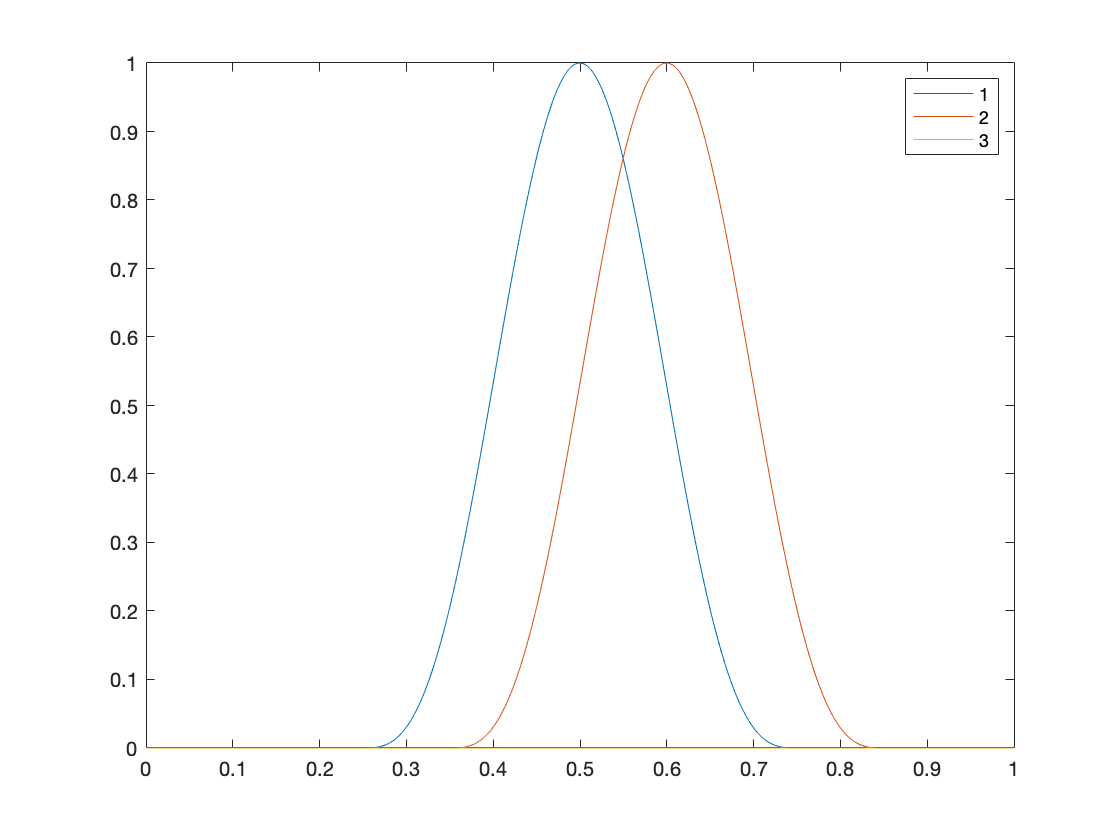

creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 2 seconds and required the additional allocation of an estimated 28 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_movieplotTFR" took 1 seconds and required the additional allocation of an estimated 8 MB
the call to "ft_movieplotER" took 1 seconds and required the additional allocation of an estimated 8 MB


sourceactivity2 = ni2_activation('ncycle', 0.5, 'frequency', 1, 'latency', 0.6);
sourceactivity3 = zeros(size(sourceactivity2));

sourcedata = [sourceactivity; sourceactivity2; sourceactivity3];
figure; plot(time, sourcedata); legend({'1', '2', '3'})

sensordata2 = leadfield * sourcedata;
ni2_topomovie(sensors, sensordata2, time);

***Describe how the topography changes over time.***

In the previous exercise we have a constructed a rotating dipole from 2 activation time courses, where the leadfields corresponding to each of the time courses were defined at a single location (with different orientation). From this situation it is just a small step to consider neural activations that are originating from different locations. The underlying mathematics is exactly the same.

sourceactivity3 = ni2_activation('ncycle', 0.4, 'frequency', 1, 'latency', 0.6);
sourcedata = [sourceactivity; sourceactivity2; sourceactivity3];
whos sourcedata

  Name            Size              Bytes  Class     Attributes

  sourcedata      3x1000            24000  double              




dippar = [0 0 8.5 0 1 0; 3 5 6 0.7 0 -0.7; -5 6 3 0.5 -0.5 0.6];
leadfield = ni2_leadfield(sensors, headmodel, dippar);

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
3 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 4 MB
computing leadfield
computing leadfield 3/3

the call to "ft_prepare_leadfield" took 1 seconds and required the additional allocation of an estimated 0 MB


sensordata3 = leadfield * sourcedata;
whos sensordata3

  Name              Size               Bytes  Class     Attributes

  sensordata3      91x1000            728000  double              



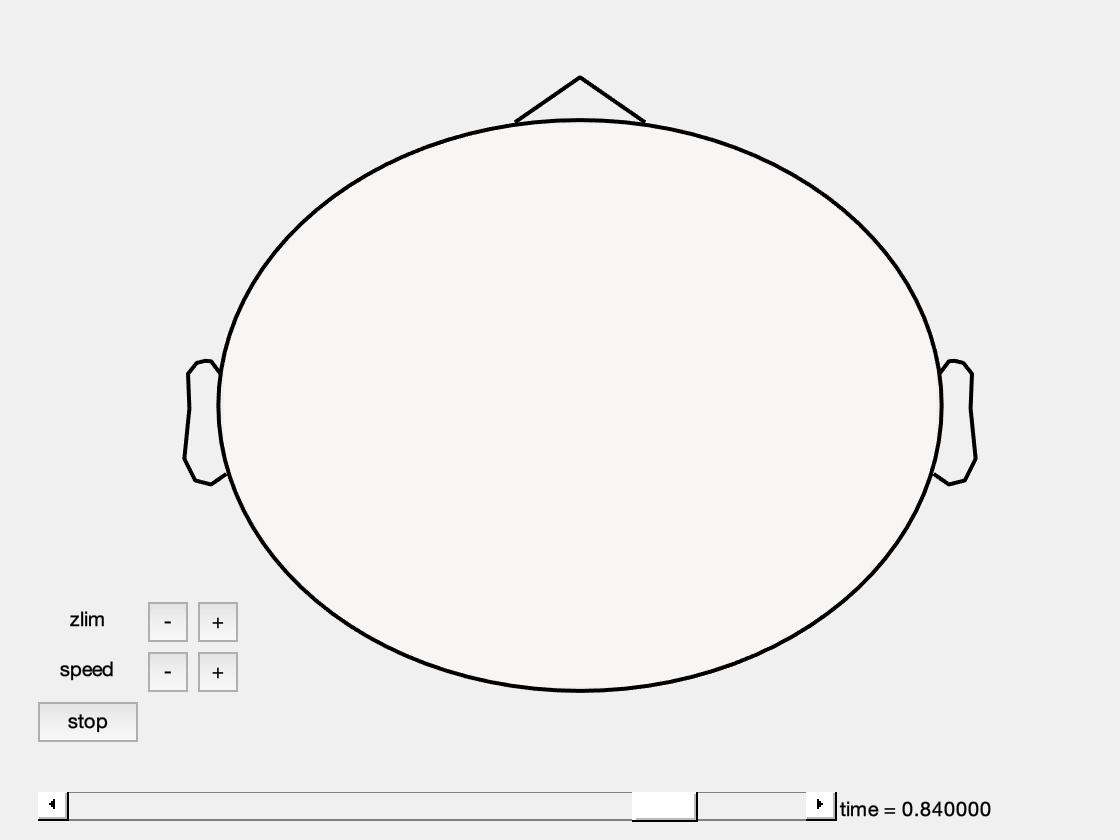

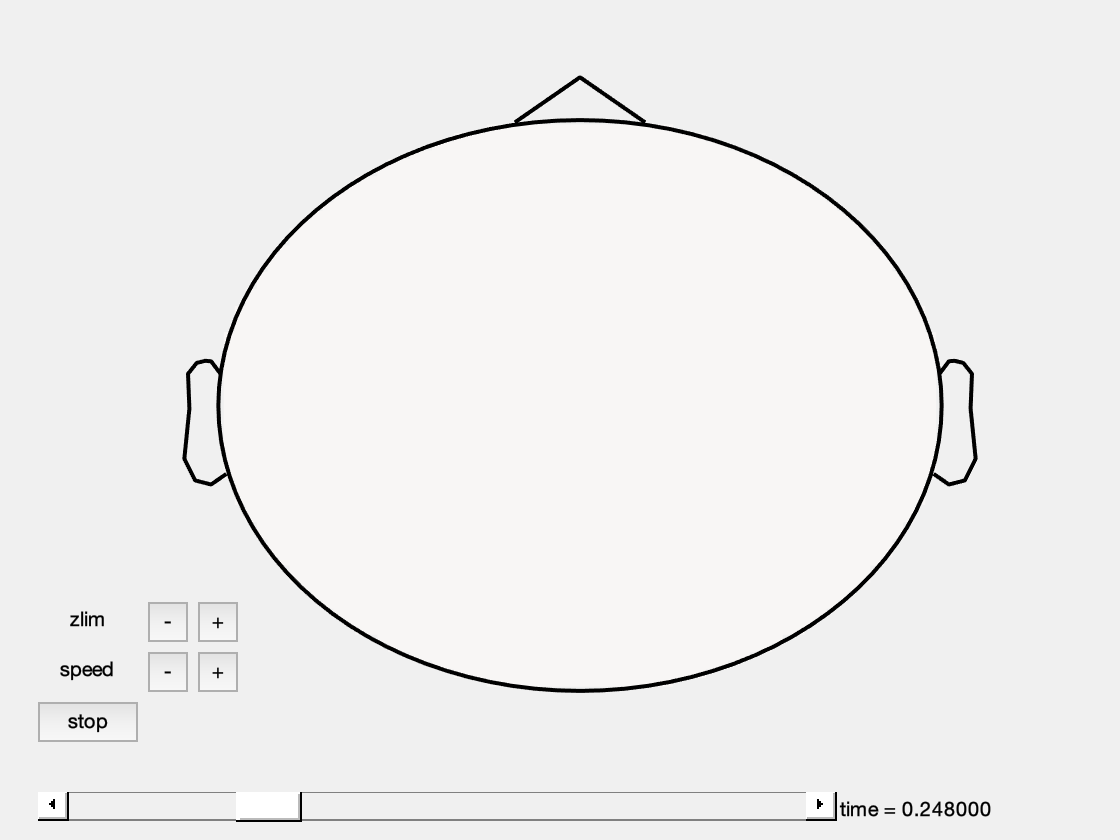

creating layout from cfg.elec
creating layout for eeg system
the call to "ft_prepare_layout" took 3 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_movieplotTFR" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_movieplotER" took 0 seconds and required the additional allocation of an estimated 4 MB


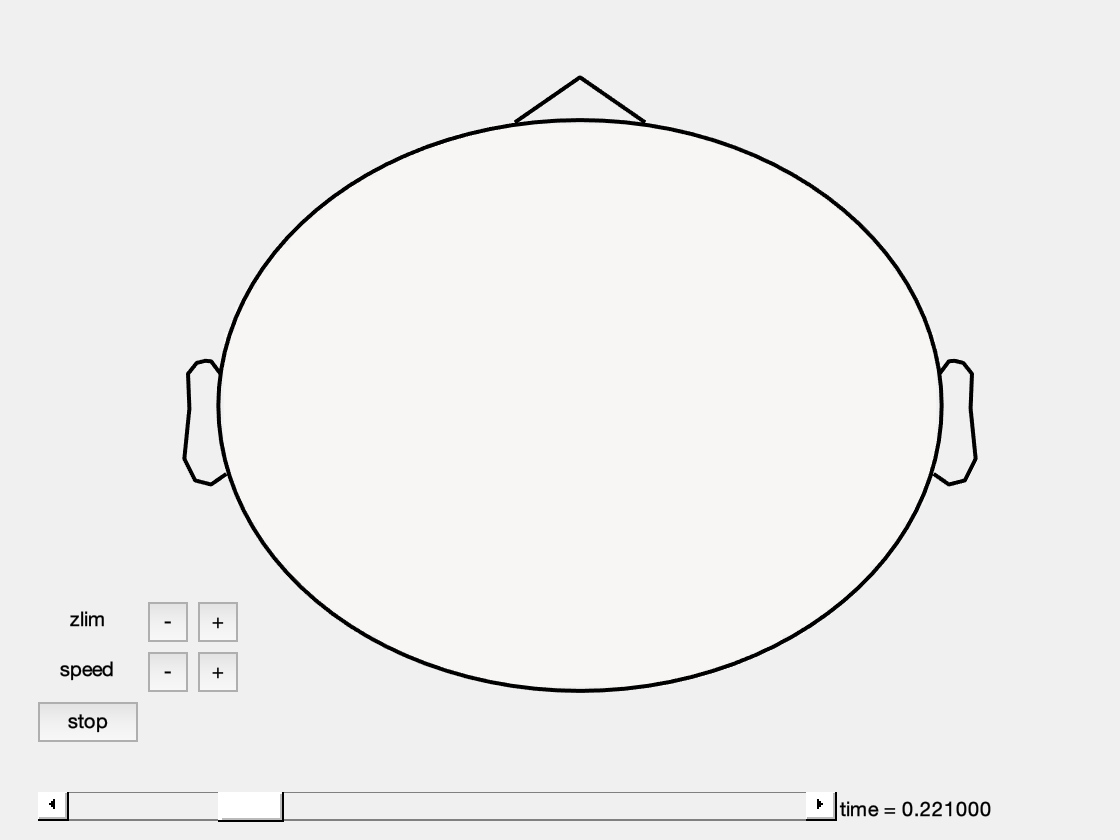

ni2_topomovie(sensors, sensordata3, time);

***Describe the changes in topography over time.***

***Create sensor data using three or four source with different activation patterns to get a feel for the mixing process. In the next class we will compare the activation patterns that you have generated, and take a vote on the most aesthetic spatiotemporal movie.***

# 5 Differences between EEG and MEG, and the issue of the EEG reference

This section deals with the fundamental differences between EEG and MEG, which is threefold: # EEG picks up more activity than MEG, # EEG signals are more blurred than MEG, and # with EEG one always has to consider the reference electrode.

After doing these exercises:

- You understand the difference between EEG and MEG in the spatial topography for a given source.

- You understand that MEG does not see all activity

- You understand the influence of the reference electrode on the spatiotemporal activation pattern.

We start with comparing spatial topographies generated by the same dipole, but measured either with EEG or with MEG.

As usual we need the following ingredients: a description of a set of sensors, a volume conduction model, and a set of source parameters. First, we do the EEG case:

dippos = [0 0 6];
dipmom = [1 0 0];
dippar = [dippos dipmom];

headmodeleeg = ni2_headmodel('type', 'spherical', 'nshell', 3);
sensorseeg = ni2_sensors('type', 'eeg');
leadfieldeeg = ni2_leadfield(sensorseeg, headmodeleeg, dippar);

We can plot the topography in 2D using:

ni2_topoplot(sensorseeg, leadfieldeeg);

or plot everything in 3D with:

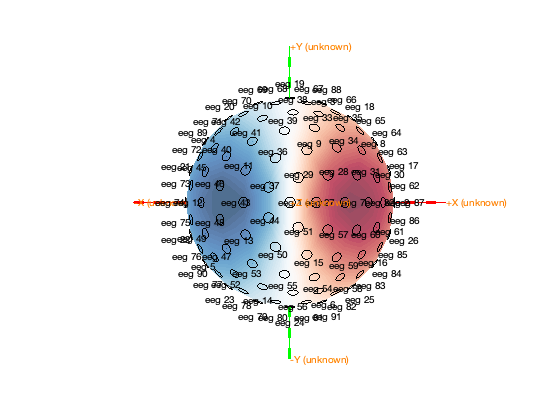

figure
ft_plot_headmodel(headmodeleeg, 'facealpha', 0.3)
ft_plot_sens(sensorseeg, 'elecshape', 'circle', 'label', 'on')
ft_plot_dipole(dippos, dipmom)
ft_plot_axes([], 'unit', 'cm')
ft_plot_topo3d(sensorseeg.chanpos, leadfieldeeg)
ft_colormap('*RdBu')

Then the MEG case:

headmodelmeg = ni2_headmodel('type', 'spherical', 'nshell', 1);
sensorsmeg = ni2_sensors('type', 'meg');
leadfieldmeg = ni2_leadfield(sensorsmeg, headmodelmeg, dippar);

Again, the topography can be ploted with:

ni2_topoplot(sensorsmeg, leadfieldmeg);

and in 3D with:

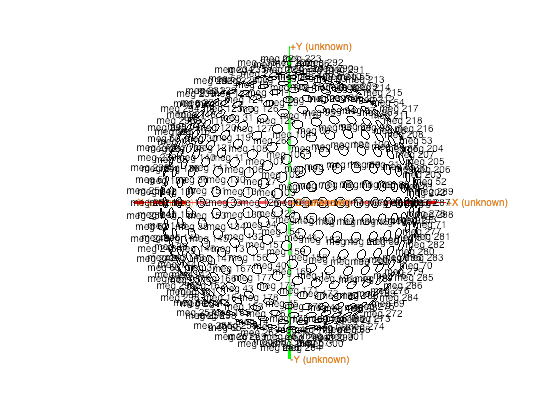

figure
ft_plot_headmodel(headmodelmeg, 'facealpha', 0.3)
ft_plot_sens(sensorsmeg, 'coilshape', 'circle', 'label', 'on')
ft_plot_dipole(dippos, dipmom)
ft_plot_axes([], 'unit', 'cm')
ft_plot_topo3d(sensorsmeg.chanpos, leadfieldmeg)
ft_colormap('*RdBu')

Note that for the MEG situation, the volume conduction model can consist of just a single sphere and the sensors are just above the head surface, not directly touching.

***Describe and explain the differences in topography.***

***Explore the effect of the source parameters on the topographies. To this end, you can vary the location of the dipole, as well as the dipole moment. In particular:***

- ***Observe what happens if you change the depth of the dipole, i.e., by moving the position closer to the center of the head.***

- ***Observe what happens if the dipole moment has a non-zero radial component, where in the extreme case the orientation is fully radial. See below for some notes with respect to dipole orientation.***

***Explore what happens if there is more than one source in the topography. For example, model 2 dipoles with positions [4 0 6] and [-4 0 6] both with a moment [1 0 0], and visualize the combined leadfield. Use matrix multiplication to do the instantaneous mixing.***

In a spherical volume conductor model, a dipole that has its orientation aligned with the radius of the sphere is called a radial dipole. More generally, if you draw a line between the origin of the sphere and the position of the dipole, the projection of the dipole moment onto this line is called the radial component (see figure). The plane perpendicular to the radius is called the tangential plane. An MEG-sensor is blind to the radial component of any dipole in a spherical volume conductor. In the most extreme case, the dipole moment is fully radially oriented, yielding to a zero magnetic field. In reality, most dipoles have both a non-zero radial component, as well as 2 tangential components. Also, realistically head-shaped volume conductors are not spherical, hence a true 'radial’ orientation does not exist.

One very important issue in EEG data analysis is the notion that we are dealing with potential differences. Typically, however, the signals are thought of as representing the electric potential measured at a particular location on the scalp. In reality the signals represent the difference in electrical potential measured at these particular locations, and the potential measured at a (distant) reference electrode. In an ideal situation the reference electrode is electrically silent, but this is never true. This is due to intrinsic electrode noise, and due to the fact that the reference electrode will also pick up some biological signal. In most practical situations, a reference electrode at the location of one of the mastoids is used. This location for sure picks up potential fluctuations due to brain activity. Therefore, EEG measurements are re-referenced to a linked-mastoid reference. As a consequence each signal represents the difference between the potential at each location and the average potential at the mastoid electrodes. This is not really an optimal referencing scheme, but it is widely used and thus facilitates comparison of results with previous literature.

We will now explore the effect of the reference on the spatiotemporal activations measured at the scalp. First we will simulate some EEG data using a single source that has some activation time course. By now the following code should start to look familiar to you.

headmodel = ni2_headmodel('type', 'spherical', 'nshell', 3);
sensors = ni2_sensors('type', 'eeg');
leadfield = ni2_leadfield(sensors, headmodel, [0 0 6 1 0 0]);

[sourceactivity, time] = ni2_activation;
sensordata = leadfield * sourceactivity;

Note the last line of code above. Remember that this represents the application of the formula for the basic observation model.

The algorithm that computes the leadfield also has to assume a reference electrode. In this case, an average reference is assumed, meaning that each of the values in the data represents the potential difference between the potential at the channel’s location and the average potential across all channels.

***Confirm that the average over all channels is zero by plotting the average versus the time. You might observe that it is slightly different from zero; that is because computers have a limited numerical precision.***

In order to emulate the situation that occurs just when the data has been recorded, we need to re-reference these data. As a reference channel we pick a channel at the bottom left of the array (channel number 74), representing the 'left mastoid’. Re-referencing is nothing else than subracting two signals. This can be easily done in MATLAB:

sensordataLM = sensordata - repmat(sensordata(74,:), [91 1]);

Now we can visualize the topography of the activity at any time point, using the plot function. Let’s use the 485th timepoint here:

ni2_topoplot(sensors, sensordata(:, 485)); colorbar

***Also visualize the re-referenced data at the same time point and describe the similarities/differences. Hint: don’t forget to look at the values that are represented by the colors, using the colorbar.***

Now have a look at the time courses, by doing:

figure; plot(time, sensordata);
figure; plot(time, sensordataLM);

***Describe the differences.***

A common re-referencing strategy is to use the linked mastoids as a reference. This is achieved by taking the data (remember: the data has been physically referenced during the recording to one of the mastoid electrodes), and subtract half of the signal recorded at the other mastoid electrode. In MATLAB it looks like this:

sensordataLMRM = sensordataLM - repmat(0.5*sensordataLM(87,:), [91 1]);

Note that we take the data as referenced to the 'left mastoid’ because this represents more realistically the data how it would be recorded. Note also, that our 'right mastoid’ corresponds with channel number 87.

***Visualize the re-referenced to linked mastoids data and compare it with the other results.***

Repeat the steps above, but now with a dipole that is close to the ‘left mastoid’ electrode, e.g. using the dipole parameters `[-7 1 1 0 1 0]`.